# **PCE VS RSM**

**This example is **with known exact solution. Compared with analytical solution, this example hopes to provide surrogate model to create 

customer defined loglikelihood to do Bayesian inference

## **1 - INITIALIZE UQLAB**

clearvars
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\NY2023\D_document\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 2 - Data for FE realization and measurement

Read measurements for each points along the beam ***Measurement Y ***(dim 10X29): 10 sets of experiments and 29 monitored points ***Z*** along 

the beam for each experiement

Measurement = xlsread("data.xlsx",'Measurement_for_surrogate','A2:AC11');

Read  FE realization  from LHS sampling

## 
$$$y = \mathcal{M}(x)$}$$
 

Dim (248X3) 

FE_Realization = xlsread("data.xlsx",'FE_models','A2:AE249');

## 2 - PRIOR DISTRIBUTION for PCE model and Bayesian inference

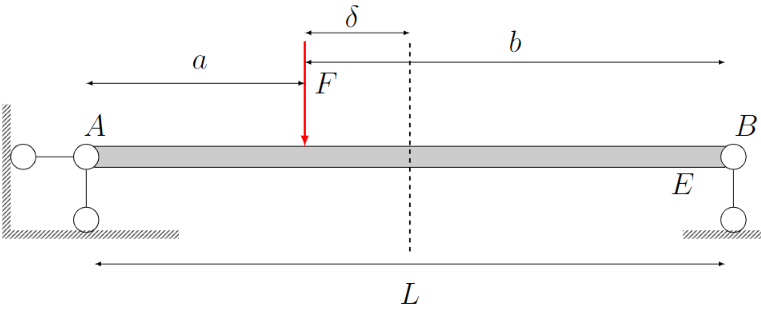

        b_b = 0.15; % beam width  (m)

        b_h = 0.3; % beam height (m)

        a % distance from the point A (m)

        b % distance from the point B (m)

        L = 30; % beam length (m)

        F = 43000;% Concentrated force (N)

%Priors on E and p
PriorOpts.Marginals(1).Name = 'E';               % Young's modulus
PriorOpts.Marginals(1).Type = 'Gaussian';
PriorOpts.Marginals(1).Moments = [25e9 5e9];   % (N/m^2)
PriorOpts.Marginals(1).Bounds = [25e9 -2*3e9, 25e9 + 2*3e9];

PriorOpts.Marginals(2).Name = 'delta';               % Concentrated load loading position
PriorOpts.Marginals(2).Type = 'Gaussian';
PriorOpts.Marginals(2).Moments = [3 5]; % (N/m)
PriorOpts.Marginals(2).Bounds = [-10, 10];

myPriorDist = uq_createInput(PriorOpts);

## 3 -  Calculate the residual ***r*****(*****x,z*****)** for surrogate model $\tilde{\mathcal{M}}$

Calculate the Root-mean-square-error  data for  surrogate

## 
$$r(\vec{x},\vec{z}) = \sqrt{\frac{1}{N}\sum_{i = 1}^{N}(Y_i - \mathcal{M}(\vec{x},\vec{z}))^2}$$


## 
$$\vec{x} = [E,\delta];\vec{z} = [z_1,z_2,...,z_{28},z_{29}];$$


$r$ is residual; $\vec{x}$ is parameters of interests; $E $ is elastic modulus; $\delta$ is the loading postion

$\vec{z} $is the different measurement points along the beam;

$\mathcal{M}$ is the FE model; $Y_i$ is the measurement data; $N$ is the number of experiment expNum.

expNum = size(Measurement,1);% experiment number  N = 10

Nreal = size (FE_Realization,1);% number of FE realization = 248

Npoint = size(Measurement,2);% number of z [z1,z2,...,z28,z29]

Residual = []; % intitail value for Residual

%loop to calculate the ResidualSum 
for i  = 1: expNum

        error = ((Measurement(i,:) - FE_Realization(1:Nreal,3:31)) ).^2;

        Residual = [Residual, sum(error,2)];
    
end

%Divide the number of experiment expNum = 10 and monitored points number along
%the beam Npoint = 29
ResidualSum = sqrt(sum(Residual,2)/expNum/Npoint);

## 4 -  Create  RSM surrogate $\tilde{\mathcal{M}}(r)$

RSM:Response surface model

%Get the residual data for RSM 

RSM_data = [FE_Realization(1:Nreal,1),FE_Realization(1:Nreal,2),ResidualSum];

Response surface model fitting

x(:,1) = RSM_data(:,1)./10e9;% normlized the E with 10e9Pa, beacuase E is too big to fit good results
x(:,2) = RSM_data(:,2)./5;% normalized the delta with deviatoin = 5m
y_fit = RSM_data(:,3); % sum error

% response surface model-- Six order polynomial equation 

model_fun_RSM = @(p,x) p(1) + ...
p(2) * x(:,1) + ...
p(3) * x(:,2) + ...
p(4) * x(:,1).^2 + ...
p(5) * x(:,2).^2 + ...
p(6) * x(:,1).^3 + ...
p(7) * x(:,2).^3 + ...
p(8) * x(:,1).^4 + ...
p(9) * x(:,2).^4 + ...
p(10) * x(:,1).^3 .* x(:,2) + ...
p(11) * x(:,1).^2 .* x(:,2).^2 + ...
p(12) * x(:,1) .* x(:,2).^3 + ...
p(13) * x(:,1).^4 .* x(:,2) + ...
p(14) * x(:,1) .* x(:,2).^4 + ...
p(15) * x(:,1).^5 + ...
p(16) * x(:,2).^5 + ...
p(17) * x(:,1).^4 .* x(:,2).^2 + ...
p(18) * x(:,1).^3 .* x(:,2).^3 + ...
p(19) * x(:,1).^2 .* x(:,2).^4 + ...
p(20) * x(:,1) .* x(:,2).^5 + ...
p(21) * x(:,1).^6 + ...
p(22) * x(:,2).^6 + ...
p(23) * x(:,1).^5 .* x(:,2) + ...
p(24) * x(:,1).^4 .* x(:,2).^2 + ...
p(25) * x(:,1).^3 .* x(:,2).^3 + ...
p(26) * x(:,1).^2 .* x(:,2).^4 + ...
p(27) * x(:,1) .* x(:,2).^5 + ...
p(28) * x(:,1).^6 .* x(:,2) + ...
p(29) * x(:,1).^5 .* x(:,2).^2 + ...
p(30) * x(:,1).^4 .* x(:,2).^3 + ...
p(31) * x(:,1).^3 .* x(:,2).^4 + ...
p(32) * x(:,1).^2 .* x(:,2).^5 + ...
p(33) * x(:,1) .* x(:,2).^6;


p0 = [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1  1 1 1 1 1 1 1 1 ];%initial value for the coeficients

[p,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(x,y_fit,model_fun_RSM,p0);

% coeficient :https://ww2.mathworks.cn/help/stats/nlinfit.html#d124e38841

Surrogate mode: Predicted vs True

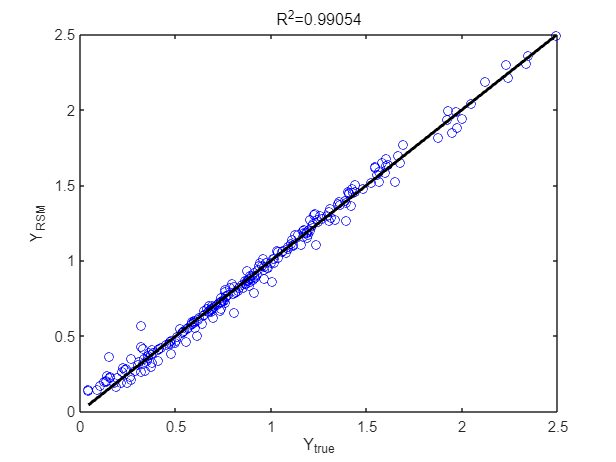


y_estimate = model_fun_RSM(p,x);
SSR = sum(R.^2); 
SST = sum((y_fit - mean(y_fit)).^2); 
R2 = 1 - SSR / SST; 
str=['R^2=', num2str(R2)];
close all;
plot(y_fit,y_estimate,'bo');
hold on;
plot([min(y_fit),max(y_fit)],[min(y_fit),max(y_fit)],'k-','LineWidth',2);
title(str);
xlabel('Y_{true}')
ylabel('Y_{RSM}')
hold off;

## 5 -  Create PCE surrogate $\tilde{\mathcal{M}}(r)$

PCE: Polynomial Chaos expansion

%Get the residual data for PCE 

PCE_data = [FE_Realization(1:Nreal,1),FE_Realization(1:Nreal,2),ResidualSum];

PCE Fitting

myPCE = PCE_create(PCE_data);

---   Calculating the PCE coefficients by regression.   ---


The estimation of PCE coefficients stopped at polynomial degree 10 and qNorm 1.00 for output variable 1
Final LOO error estimate: 4.064805e-01
---                 Calculation finished!                               ---


Print a summary of the resulting PCE metamodel:

uq_print(myPCE)

%------------ Polynomial chaos output ------------%
   Number of input variables:    2
   Maximal degree:               10
   q-norm:                       1.00
   Size of full basis:           66
   Size of sparse basis:         5
   Full model evaluations:       248
   Leave-one-out error:          3.9285616e-01
   Modified leave-one-out error: 4.0648052e-01
   Mean value:                   0.8220
   Standard deviation:           0.2572
   Coef. of variation:            31.295%
%--------------------------------------------------%


hold on

Plot the true vs. predicted values:

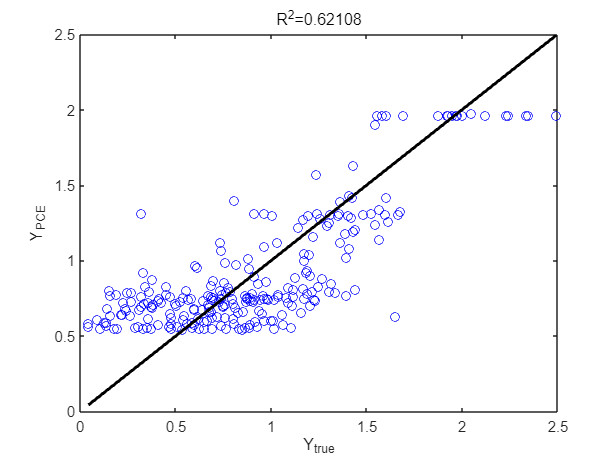

%Obtain the X_val and YPCE/Y_val
X_val(:,1) = PCE_data(1:Nreal,1);
X_val(:,2) = PCE_data(1:Nreal,2);
YPCE = uq_evalModel(myPCE,X_val);
Y_val = PCE_data(1:Nreal,3);
R = Y_val - YPCE;
SSR = sum(R.^2); 
SST = sum((Y_val - mean(Y_val)).^2); 
R2 = 1 - SSR / SST; 
str=['R^2=', num2str(R2)];
close all;
plot(Y_val,YPCE,'bo');
hold on;
plot([min(Y_val),max(Y_val)],[min(Y_val),max(Y_val)],'k-','LineWidth',2);
title(str);
xlabel('Y_{true}')
ylabel('Y_{PCE}')
hold off;

Export the PCE strucuture

save myPCE

## 6 - Define the priors for discrepancy $\sigma$

By default, UQlab assumes an independent and identically distributed discrepancy

$\varepsilon \sim \mathcal{N}(0,\mu_{y}^2)$, with $\mu_{y} = \frac{1}{N}\sum_{i = 1}^{N}y_i$

PriorOpts.Marginals(3).Name = 'sigma2'; % variance
PriorOpts.Marginals(3).Type = 'Uniform';
sigma2 = mean(Measurement(:,:),"all");
PriorOpts.Marginals(3).Parameters = [0 sigma2^2];
myPriorDist = uq_createInput(PriorOpts);

## 7 - Define the custom-loglikelihood  and measurement data for UQlab calculation


$$    \log  \mathcal{L} (\mathcal{\Theta }) = \sum_{i=1}^{N}\left(-\frac{1}{2}\left(r_i(\vec{x},\vec{z})\right)^{T} \Sigma(\epsilon)^{-1}\left(r_i(\vec{x},\vec{z})\right)\right) - \frac{3N}{2}\log(2\pi) - \frac{N}{2}\log\left(\det(\Sigma(\epsilon))\right)$$


Monitored data $Y_i$ for beam deflection have been used in PCE surrogate model. No measurements available for Bayesian inference: Pass zeros  to measurement $Y_i$ just for calculation, which equals:

## 
$$r(\vec{x},\vec{z}) \sim (0- r(\vec{x},\vec{z}) ) \sim (Y_i - \mathcal{M}(\vec{x},\vec{z}))}$$


$r(\vec{x},\vec{z})$ dim 248X1 $\sim$ $(Y_i - \mathcal{M}(\vec{x},\vec{z}))}$ dim 248X29

Also, measurement data for $Y_{10 X 29}$ changed into $Y_{10X1}$

y = zeros(1,1);
myData.y = y;
myData.Name = 'Zeros vector measurement for Bayesian inference';

Loglikelihood still follows the Gaussian discrepancy criteria

myLogLikeli = @(params,y) myLogLikeli2(params,y);

## 8 - Solver options

Solver.Type = 'MCMC';
Solver.MCMC.Visualize.Parameters = [1 2];
Solver.MCMC.Visualize.Interval = 10;
Solver.MCMC.Sampler = 'AIES';
Solver.MCMC.Steps = 500;
Solver.MCMC.NChains = 5;
Solver.MCMC.Proposal.PriorScale = 1e-3;